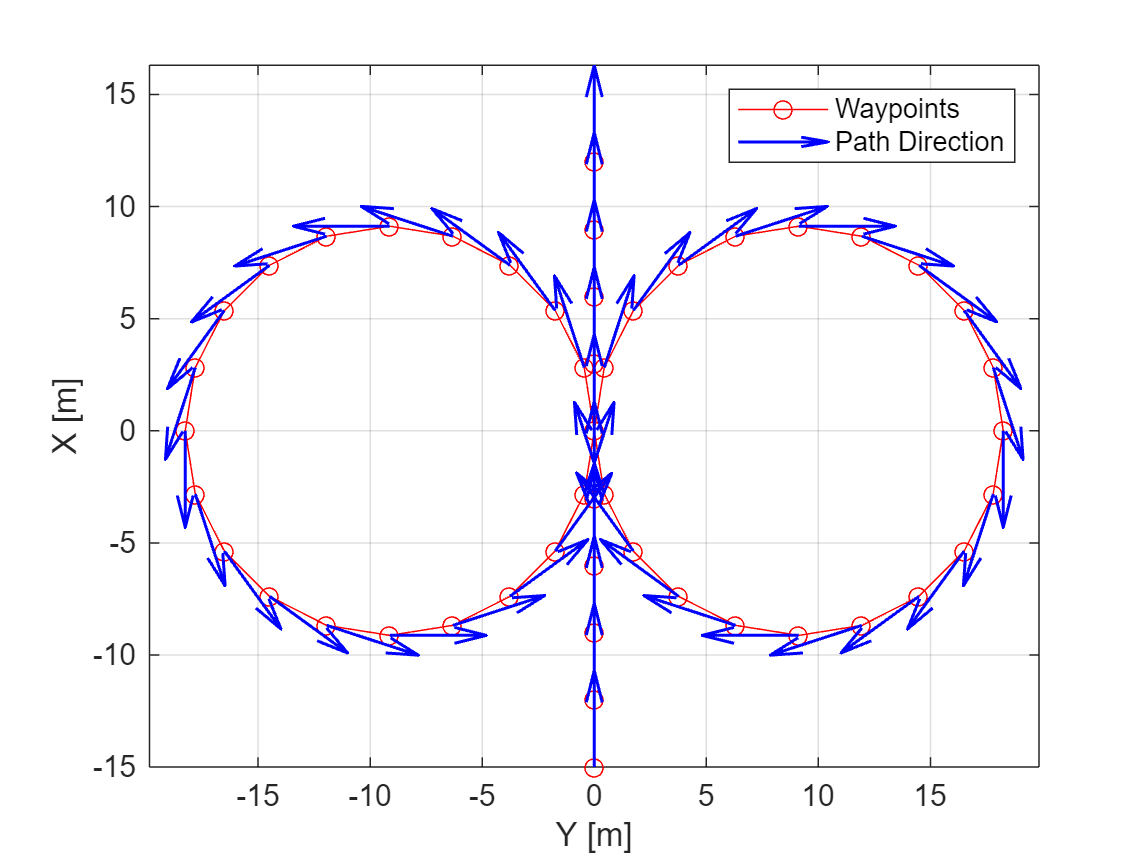

open_system('vdynblksskidpad');

mdlWks = get_param('vdynblksskidpad','ModelWorkspace');
TrackPoints = evalin(mdlWks,'TrackPoints');
figure;
plot(TrackPoints(:,2),TrackPoints(:,1),'ro-')
hold on
arrowLen = 1.5;
quiver(TrackPoints(:,2),TrackPoints(:,1),arrowLen*sin(TrackPoints(:,3)),arrowLen*cos(TrackPoints(:,3)),'b','LineWidth',1,'MaxHeadSize',arrowLen)
box on
grid on
xlabel('Y [m]')
ylabel('X [m]')
axis equal
legend('Waypoints','Path Direction')

vehicle type as "Game Engine Physics"

vehType = "Game Engine Physics"

vehType = "Game Engine Physics"

% set_param( 'vdynblksskidpad/Formula Student Vehicle','vehType',vehType);

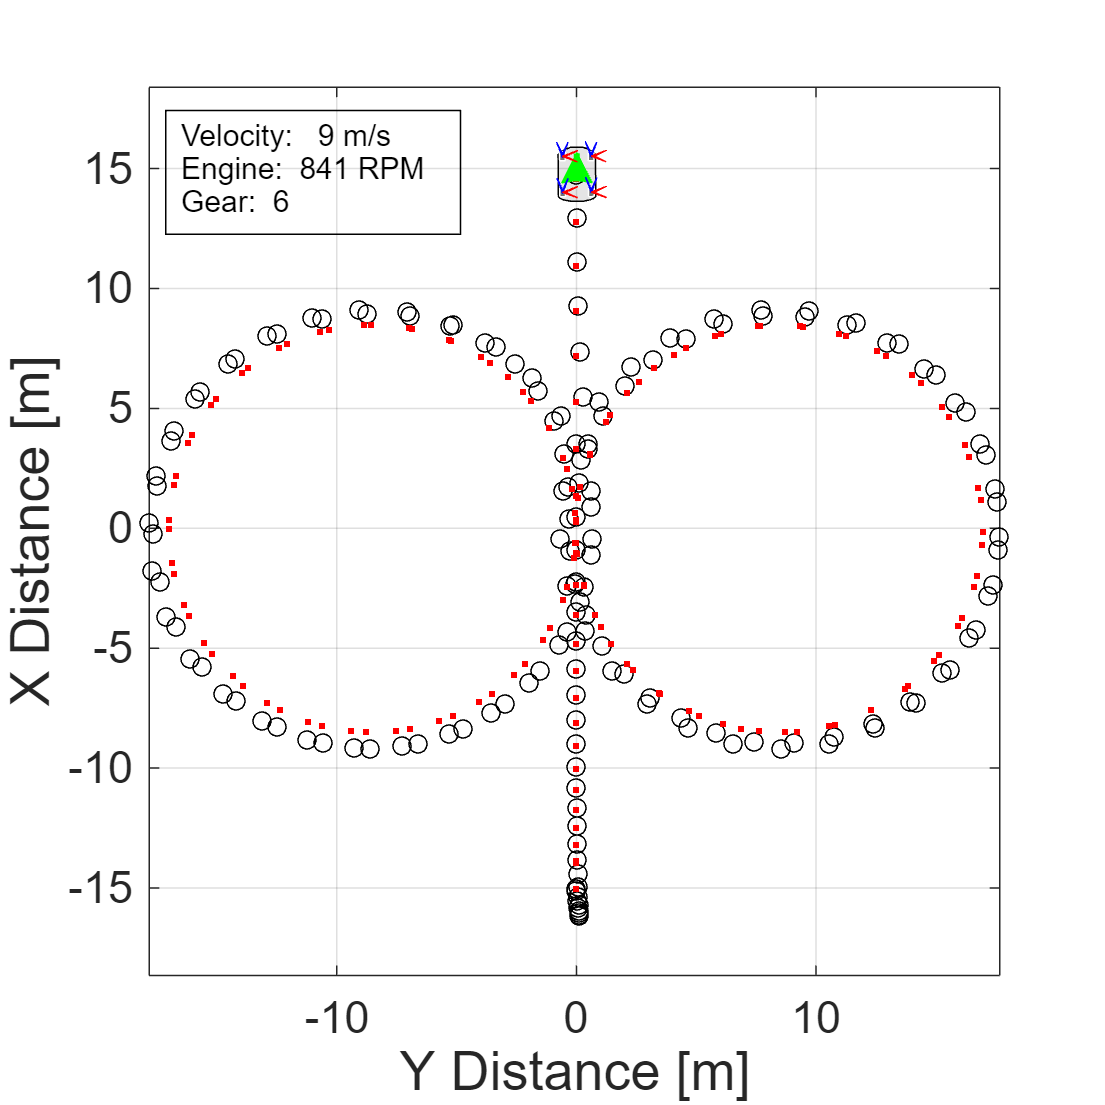

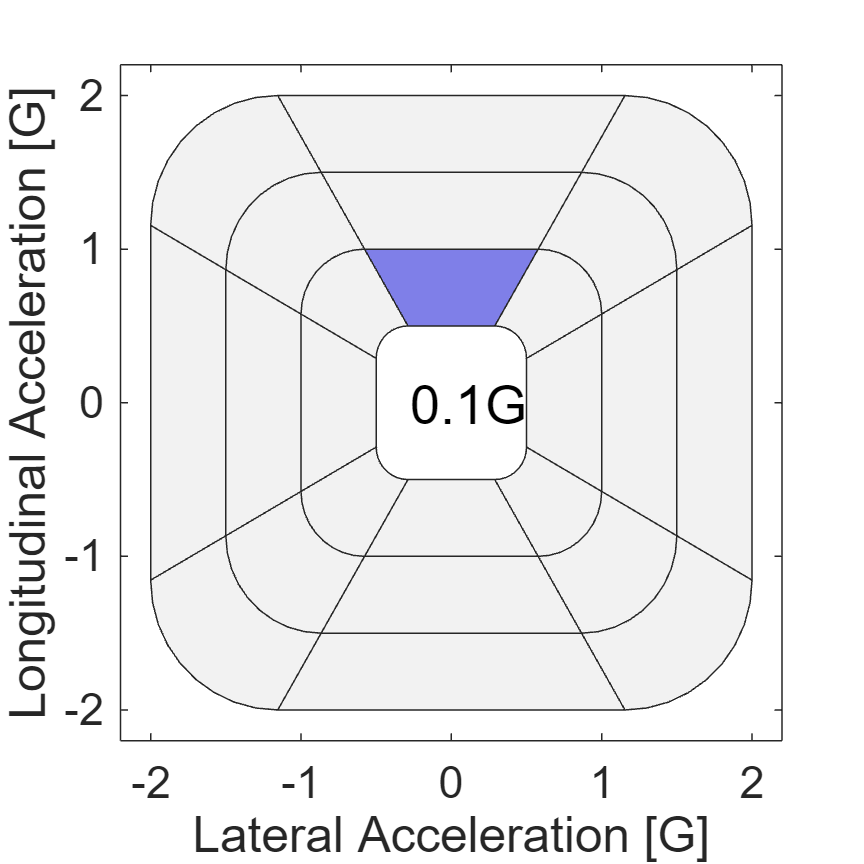

 set_param('vdynblksskidpad/Visualization/3D Visualization','engine3D','Enabled - Simulink 3D Vehicle')
 set_param('vdynblksskidpad/Visualization/3D Visualization','conesOn','on');
 set_param('vdynblksskidpad','SimulationCommand','update')
 set_param('vdynblksskidpad/Simulation 3D Camera','mountLoc','Roll bar center')
 newThreshold=0.47;
 set_param('vdynblksskidpad/Deep Learning Object Detector', 'threshold', num2str(newThreshold))
 sim('vdynblksskidpad');

 save_system('vdynblksskidpad');
 close_system('vdynblksskidpad');

You can also place cones with Simulink 3D Animation to better define the skid pad course when using the 3D visualization engine. You can adjust cone placement through the initialization script in the Simulation 3D Actor block.